% --- 1. PARAMETRI INIZIALI E CARICAMENTO DATI ---
num_pos = 5;
num_acq = 25;
k_folds = 5;
num_iterazioni = 10;
dim_fold = num_acq / k_folds; 
totale_test = num_iterazioni * num_pos * num_acq; % 1250 classificazioni singole

primo_dato = load('Z_1_1.mat');
N_punti_originali = length(primo_dato.misura_Ztrans.f_MHz);
f_MHz = primo_dato.misura_Ztrans.f_MHz; % Estrazione asse frequenze[cite: 1]
AllData = zeros(N_punti_originali, num_acq, num_pos);

fprintf('Caricamento dati in memoria...\n');

Caricamento dati in memoria...


for x = 1:num_pos
    for y = 1:num_acq
        try
            dati = load(sprintf('Z_%d_%d.mat', x, y));
            AllData(:, y, x) = abs(dati.misura_Ztrans.S_mean); %[cite: 1]
        catch
            AllData(:, y, x) = NaN;
        end
    end
end

% Calcolo della Media Globale per i grafici finali (tutte le 25 acquisizioni)
Media_Globale = squeeze(mean(AllData, 2, 'omitnan')); 

% --- 2. SETUP DEL SOTTOCAMPIONAMENTO E PREALLOCAZIONE ---
passi_decimazione = [1, 2, 5, 10, 20, 50, 100, 200];
num_step = length(passi_decimazione);

Acc_RMSE = zeros(1, num_step);
Acc_Pearson = zeros(1, num_step);
Lat_Singola_RMSE = zeros(1, num_step);     
Lat_Singola_Pearson = zeros(1, num_step);  
Num_Punti_Attivi = zeros(1, num_step);

% Strutture (Cell Arrays) per memorizzare tutte le predizioni per i grafici finali
Store_Veri = cell(1, num_step);
Store_Pred_RMSE = cell(1, num_step);
Store_Pred_Pearson = cell(1, num_step);

fprintf('\nAvvio Benchmark: Accuratezza vs Latenza per Singolo Segnale\n');


Avvio Benchmark: Accuratezza vs Latenza per Singolo Segnale


fprintf('-------------------------------------------------------------------------------\n');

-------------------------------------------------------------------------------


fprintf('Punti\t| Acc. RMSE\t| Acc. Pearson\t| Lat. RMSE (µs) | Lat. Pearson (µs)\n');

Punti	| Acc. RMSE	| Acc. Pearson	| Lat. RMSE (µs) | Lat. Pearson (µs)


fprintf('-------------------------------------------------------------------------------\n');

-------------------------------------------------------------------------------



% --- 3. CICLO SUI DIVERSI LIVELLI DI DECIMAZIONE ---
for s = 1:num_step
    passo = passi_decimazione(s);
    Dati_Ridotti = AllData(1:passo:end, :, :);
    Num_Punti_Attivi(s) = size(Dati_Ridotti, 1);
    N_punti_corr = Num_Punti_Attivi(s);
    
    Etichette_Vere = zeros(1, totale_test);
    Predizioni_RMSE = zeros(1, totale_test);
    Predizioni_Pearson = zeros(1, totale_test);
    indice_globale = 1;
    
    tempo_tot_rmse = 0;
    tempo_tot_pearson = 0;
    
    for iter = 1:num_iterazioni
        indici_perm = zeros(num_pos, num_acq);
        for x = 1:num_pos
            indici_perm(x, :) = randperm(num_acq);
        end
        
        for fold = 1:k_folds
            idx_start = (fold - 1) * dim_fold + 1;
            idx_end = fold * dim_fold;
            
            LUT = zeros(N_punti_corr, num_pos);
            test_indices_per_pos = zeros(num_pos, dim_fold);
            
            % Training
            for x = 1:num_pos
                idx_test = indici_perm(x, idx_start:idx_end);
                test_indices_per_pos(x, :) = idx_test;
                idx_train = setdiff(indici_perm(x, :), idx_test);
                LUT(:, x) = mean(Dati_Ridotti(:, idx_train, x), 2, 'omitnan');
            end
            
            % Testing
            for x_vero = 1:num_pos
                for j = 1:dim_fold
                    idx_acq_test = test_indices_per_pos(x_vero, j);
                    segnale_test = Dati_Ridotti(:, idx_acq_test, x_vero);
                    
                    % Classificazione RMSE
                    distanze_rmse = zeros(1, num_pos);
                    t_start_rmse = tic;
                    for classe_lut = 1:num_pos
                        distanze_rmse(classe_lut) = sqrt(mean((segnale_test - LUT(:, classe_lut)).^2, 'omitnan'));
                    end
                    [~, pred_rmse] = min(distanze_rmse);
                    tempo_tot_rmse = tempo_tot_rmse + toc(t_start_rmse);
                    
                    % Classificazione PEARSON
                    correlazioni = zeros(1, num_pos);
                    t_start_pearson = tic;
                    if N_punti_corr > 2
                        for classe_lut = 1:num_pos
                            R = corrcoef(segnale_test, LUT(:, classe_lut), 'Rows', 'complete');
                            correlazioni(classe_lut) = R(1, 2);
                        end
                    else
                        correlazioni(:) = -1;
                    end
                    [~, pred_pearson] = max(correlazioni);
                    tempo_tot_pearson = tempo_tot_pearson + toc(t_start_pearson);
                    
                    % Salvataggio vettori
                    Etichette_Vere(indice_globale) = x_vero;
                    Predizioni_RMSE(indice_globale) = pred_rmse;
                    Predizioni_Pearson(indice_globale) = pred_pearson;
                    indice_globale = indice_globale + 1;
                end
            end
        end
    end
    
    % Metriche finali per lo step
    Acc_RMSE(s) = sum(Etichette_Vere == Predizioni_RMSE) / totale_test * 100;
    Acc_Pearson(s) = sum(Etichette_Vere == Predizioni_Pearson) / totale_test * 100;
    Lat_Singola_RMSE(s) = (tempo_tot_rmse / totale_test) * 1e6;
    Lat_Singola_Pearson(s) = (tempo_tot_pearson / totale_test) * 1e6;
    
    % Salvataggio nello storico per la generazione grafici
    Store_Veri{s} = Etichette_Vere;
    Store_Pred_RMSE{s} = Predizioni_RMSE;
    Store_Pred_Pearson{s} = Predizioni_Pearson;
    
    fprintf('%d\t| %.2f%%\t| %.2f%%\t| %10.2f\t | %10.2f\n', ...
        Num_Punti_Attivi(s), Acc_RMSE(s), Acc_Pearson(s), Lat_Singola_RMSE(s), Lat_Singola_Pearson(s));
end

1001	| 100.00%	| 100.00%	|      53.22	 |     265.78
501	| 100.00%	| 100.00%	|      35.12	 |     181.43
201	| 100.00%	| 100.00%	|      32.37	 |     172.33
101	| 100.00%	| 100.00%	|      28.77	 |     162.83
51	| 100.00%	| 100.00%	|      29.81	 |     163.69
21	| 100.00%	| 100.00%	|      28.64	 |     163.08
11	| 93.92%	| 99.12%	|      29.35	 |     165.94
6	| 88.96%	| 88.08%	|      27.50	 |     146.33


fprintf('-------------------------------------------------------------------------------\n');

-------------------------------------------------------------------------------


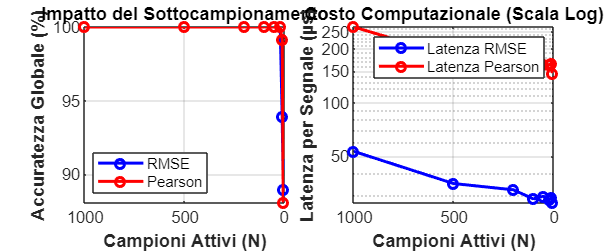


% =========================================================================
% --- 4. GENERAZIONE DELLE FIGURE PER LA TESI ---
% =========================================================================
set(0, 'DefaultAxesFontSize', 12); % Aumenta font per leggibilità nella tesi

% --- FIGURA 1: Degrado Accuratezza e Latenza ---
figure('Name', 'Fig 1: Benchmark Globale', 'Position', [50, 50, 1100, 450], 'Color', 'w');
subplot(1, 2, 1);
plot(Num_Punti_Attivi, Acc_RMSE, '-ob', 'LineWidth', 2, 'DisplayName', 'RMSE'); hold on; grid on;
plot(Num_Punti_Attivi, Acc_Pearson, '-or', 'LineWidth', 2, 'DisplayName', 'Pearson');
set(gca, 'XDir', 'reverse'); 
xlabel('Campioni Attivi (N)', 'FontWeight', 'bold'); ylabel('Accuratezza Globale (%)', 'FontWeight', 'bold');
title('Impatto del Sottocampionamento'); legend('Location', 'southwest');

subplot(1, 2, 2);
semilogy(Num_Punti_Attivi, Lat_Singola_RMSE, '-ob', 'LineWidth', 2, 'DisplayName', 'Latenza RMSE'); hold on; grid on;
semilogy(Num_Punti_Attivi, Lat_Singola_Pearson, '-or', 'LineWidth', 2, 'DisplayName', 'Latenza Pearson');
set(gca, 'XDir', 'reverse');
xlabel('Campioni Attivi (N)', 'FontWeight', 'bold'); ylabel('Latenza per Segnale (µs)', 'FontWeight', 'bold');
title('Costo Computazionale (Scala Log)'); legend('Location', 'northeast');

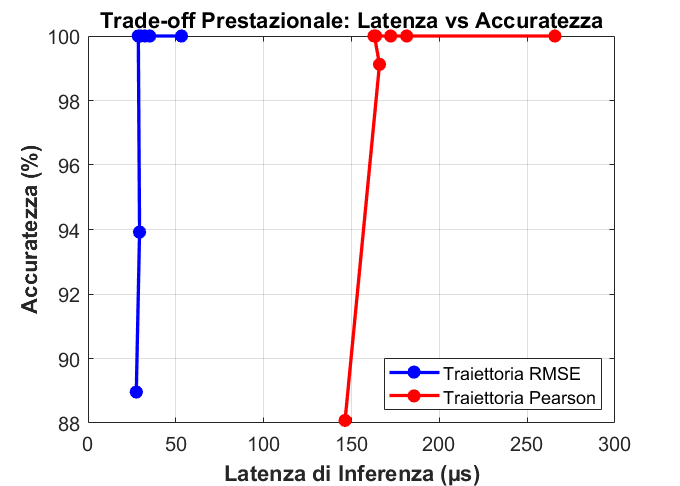


% --- FIGURA 2: Trade-off Pareto (Accuratezza vs Latenza) ---
figure('Name', 'Fig 2: Pareto Trade-off', 'Position', [100, 100, 700, 500], 'Color', 'w');
plot(Lat_Singola_RMSE, Acc_RMSE, '-ob', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'DisplayName', 'Traiettoria RMSE'); hold on; grid on;
plot(Lat_Singola_Pearson, Acc_Pearson, '-or', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'DisplayName', 'Traiettoria Pearson');
xlabel('Latenza di Inferenza (µs)', 'FontWeight', 'bold'); ylabel('Accuratezza (%)', 'FontWeight', 'bold');
title('Trade-off Prestazionale: Latenza vs Accuratezza');
legend('Location', 'southeast');

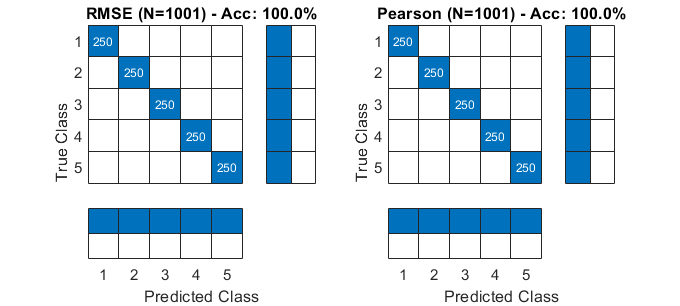

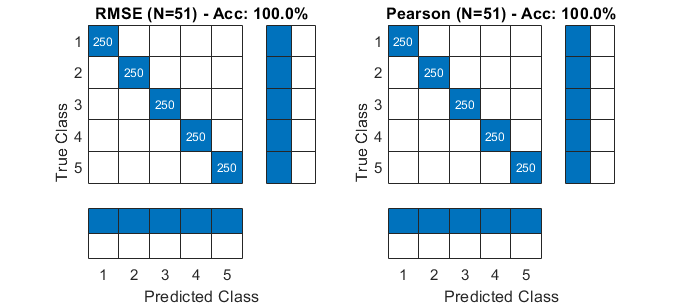

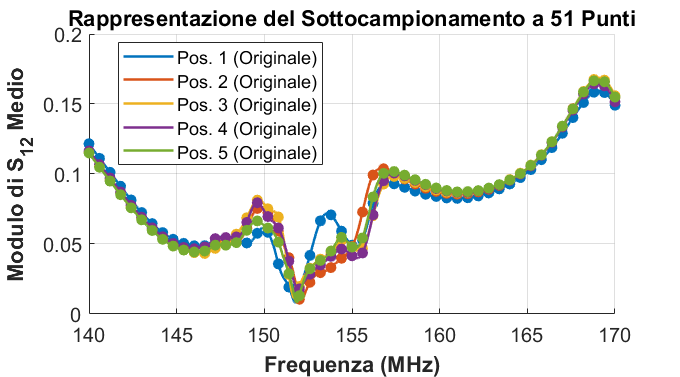

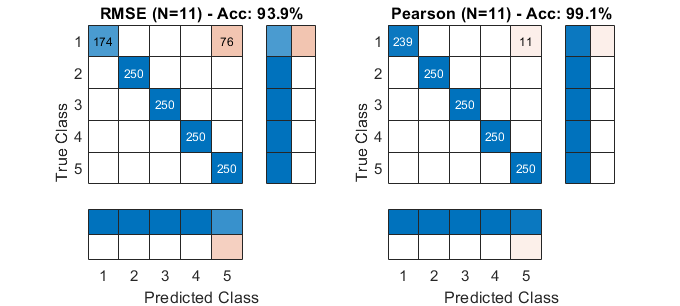

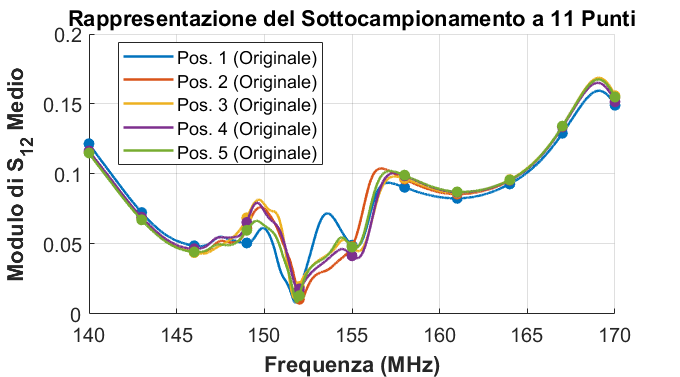


% --- CICLO PER GENERARE FOCUS SPECIFICI (1001, 51, 11 Punti) ---
target_punti = [1001, 51, 11];

for i = 1:length(target_punti)
    N_target = target_punti(i);
    idx_step = find(Num_Punti_Attivi == N_target, 1);
    passo_corrente = passi_decimazione(idx_step);
    
    if isempty(idx_step)
        continue;
    end
    
    % Recupero predizioni salvate
    Y_Veri = Store_Veri{idx_step};
    Y_Pred_RMSE = Store_Pred_RMSE{idx_step};
    Y_Pred_Pearson = Store_Pred_Pearson{idx_step};
    
    % --- FIGURA: MATRICI DI CONFUSIONE ---
    fig_name = sprintf('Matrici Confusione (N=%d)', N_target);
    figure('Name', fig_name, 'Position', [150 + i*20, 150 + i*20, 1000, 450], 'Color', 'w');
    
    subplot(1, 2, 1);
    cm_r = confusionchart(Y_Veri, Y_Pred_RMSE, 'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized');
    cm_r.Title = sprintf('RMSE (N=%d) - Acc: %.1f%%', N_target, Acc_RMSE(idx_step));
    
    subplot(1, 2, 2);
    cm_p = confusionchart(Y_Veri, Y_Pred_Pearson, 'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized');
    cm_p.Title = sprintf('Pearson (N=%d) - Acc: %.1f%%', N_target, Acc_Pearson(idx_step));
    
    % --- FIGURA: SEGNALI MEDI CON MARKER (Solo per N=51 e N=11) ---
    if N_target < 1001
        fig_name_sig = sprintf('Segnali e Campionamento (N=%d)', N_target);
        figure('Name', fig_name_sig, 'Position', [200 + i*20, 200 + i*20, 900, 500], 'Color', 'w');
        hold on; grid on;
        colori = lines(num_pos);
        
        idx_campionamento = 1:passo_corrente:N_punti_originali;
        
        for x = 1:num_pos
            % Curva continua (Baseline 1001 punti)
            plot(f_MHz, Media_Globale(:, x), '-', 'Color', [colori(x,:) 0.4], 'LineWidth', 1.5, ...
                'DisplayName', sprintf('Pos. %d (Originale)', x));
            
            % Punti campionati
            plot(f_MHz(idx_campionamento), Media_Globale(idx_campionamento, x), 'o', ...
                'Color', colori(x,:), 'MarkerFaceColor', colori(x,:), 'MarkerSize', 6, ...
                'HandleVisibility', 'off'); 
        end
        
        xlabel('Frequenza (MHz)', 'FontWeight', 'bold');
        ylabel('Modulo di S_{12} Medio', 'FontWeight', 'bold');
        title(sprintf('Rappresentazione del Sottocampionamento a %d Punti', N_target));
        legend('Location', 'best');
        hold off;
    end
end